%Jack Cornwall C0037685 01/11/22
%PM2 Portfolio 1 Question 2 
%Using Eulers method to solve ODE given differing intial conditions

%clearing memory to ensure nothing remains from previous loops/ held plots
clear all

%delcaring symbolic varialbes for exact analytical solution
syms T

%values of p & a
p = 10e5

p = 1000000

a = 0.0005;
p/a

ans = 2.0000e+09


%creating initial conditions for sol_1 & sol_2
n1(1) = 0; %initial condtions when n(0)=0
n2(1) = 2*(p/a) %initial condition when n(0)=2*(p/a)

n2 = 4.0000e+09


%creating time steps
h = 0.0005; %size of time step
tf = 0.025; %full amount of time
t = 0:h:tf; %creating all time steps
mod(tf,h) %remainder of tf/h must be zero!

ans = 0

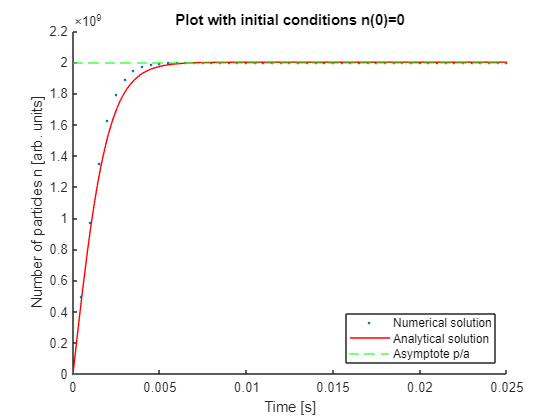


%looping through time
for N = 2:1:tf/h + 1
    
    %for de-bugging
    N; %print out number of current step
    t(N); %prints out current time

    %calculating next n value for both scenarios
    n1(N) = n1(N-1) + h*((p^2) - (a^2)*(n1(N-1)^2));
    n2(N) = n2(N-1) + h*((p^2) - (a^2)*(n2(N-1)^2));

end

sol1(T) = (p/a)*tanh(p*a*T);
sol2(T) = (p/a)*(((3*exp(2*p*a*T))+1)/((3*exp(2*p*a*T))-1));

%%plotting scenario 1 t(0)=0%%
plot(t,n1,".") %plotting numerical solution 1
hold on %plotting on same graph

fplot(sol1(T),"-r") %plotting analytical solution 1
yline(p/a,"g--") %adding asymptote

%setting limits
xlim([0 tf]) %x lims
ylim([0 (p/a)*1.1]) %y lims

hold off %end plotting on same graph

%beautifying plot
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("Time [s]");
ylabel("Number of particles n [arb. units]");
title('Plot with initial conditions n(0)=0')
legend("Numerical solution","Analytical solution","Asymptote p/a","location","southeast")

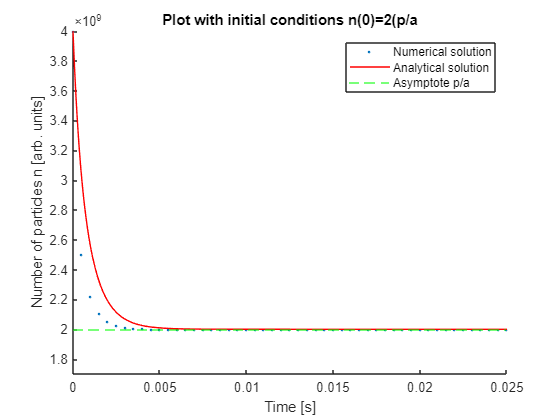


%%plotting scenario 2 t(0)=2*(p/a)%%
plot(t,n2,".") %plotting numerical solution 2
hold on %plotting on same graph

fplot(sol2(T),"-r") %plotting analytical solution 2
yline(p/a,"g--") %adding asymptote

%setting limits
xlim([0 tf]) %x lims
ylim([(p/a)*0.85 (p/a)*2]) %y lims

hold off %end plotting on same graph

%beautifying plot
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("Time [s]");
ylabel("Number of particles n [arb. units]");
title('Plot with initial conditions n(0)=2(p/a')
legend("Numerical solution","Analytical solution","Asymptote p/a","location","northeast")